# **TP3 : Traitement d'image et interprétation**

clc;
clear;
close all;

## Introduction

im1 = imread('cameraman.tif');
disp(["La taille de l'image est de ",num2str(size(im1))])

    "La taille de l'image est de "    "256  256"



m = 256;
n = 256,

n = 256

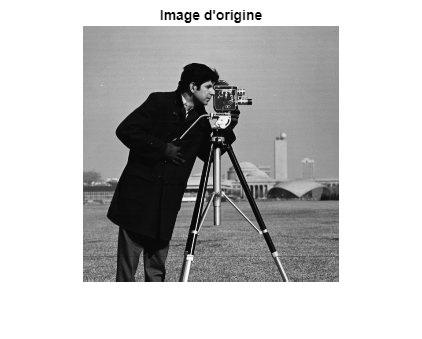

figure
imshow(im1)
title("Image d'origine")

La détection de contours vise à identifier les points d'une image où se produisent des variations abruptes d'intensité lumineuse. Ces variations traduisent généralement des éléments significatifs, tels que des événements visuels importants ou des formes à détecter.

Certaines méthodes de détection s'appuient sur l'application de filtres linéaires, une opération souvent désignée sous le nom de **rehaussement de contours**. Ces filtres sont définis par un masque h(m,n) de dimensions $M_h \cdot N_h$�, qui est appliqué à l'image pour accentuer les zones de transitions lumineuses marquées.

## Exercice 1 :

### 1/ Filtres gradients

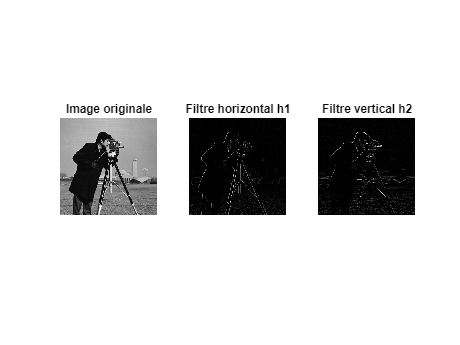

% Sans la toolbox
% Définition des filtres
h1 = [1 -1];
h2 = [1; -1];

% Initialisation des images filtrées
I1f1 = zeros(m, n); % Pour le filtre horizontal
I1f2 = zeros(m, n); % Pour le filtre vertical

% Application du filtre horizontal (h1)
for i = 1:m
    for j = 1:n-1 
        I1f1(i, j,:) = im1(i, j) - im1(i, j+1);
    end
end

% Application du filtre vertical (h2)
for i = 1:m-1 
    for j = 1:n
        I1f2(i, j) = im1(i, j) - im1(i+1, j);
    end
end  

% Affichage des résultats
figure;
subplot(1, 3, 1);
imshow(im1);
title('Image originale');

subplot(1, 3, 2);
imshow(I1f1,[]);
title('Filtre horizontal h1');

subplot(1, 3, 3);
imshow(I1f2,[]);
title('Filtre vertical h2');

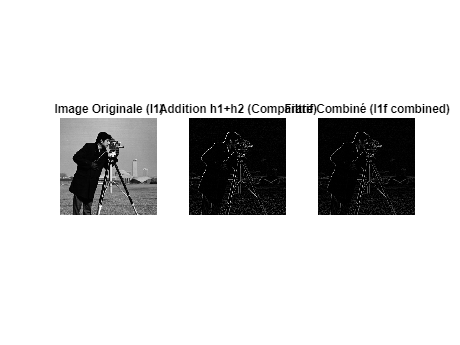


% Appliquer le filtre h1 et h2

% Masques des filtres
h1 = [1, -1]; % Filtre horizontal
h2 = [1; -1]; % Filtre vertical

% Initialiser les matrices pour les résultats
I1f1 = zeros(m, n); % Résultat du filtre horizontal
I1f2 = zeros(m, n); % Résultat du filtre vertical
I1f_combined = zeros(m, n); % Résultat combiné

% Appliquer le filtre horizontal (h1)
for i = 1:m
    for j = 1:(n-1) % Ne pas filtrer le dernier pixel de chaque ligne
        I1f1(i, j) = im1(i, j) * h1(1) - im1(i, j+1);
    end
    I1f1(i, n) = im1(i, n); % Garder le dernier pixel inchangé
end

% Appliquer le filtre vertical (h2)
for j = 1:n
    for i = 1:(m-1) % Ne pas filtrer le dernier pixel de chaque colonne
        I1f2(i, j) = im1(i, j) * h2(1) - im1(i+1, j);
    end
    I1f2(m, j) = im1(m, j); % Garder le dernier pixel inchangé
end

% Combinaison des deux filtres
for i = 1:m
    for j = 1:n
        I1f_combined(i, j) = sqrt(I1f1(i, j)^2 + I1f2(i, j)^2);
    end
end

% Affichage des résultats
figure;

% Image originale
subplot(1, 3, 1);
imshow(uint8(im1),[]);
title('Image Originale (I1)');

% Image combinée des deux filtres
subplot(1, 3, 3);
imshow(uint8(I1f_combined),[]);
title('Filtre Combiné (I1f combined)');

% Affichage intermédiaire (pour comparaison)
subplot(1, 3, 2);
imshow(uint8(I1f1 + I1f2),[]);
title('Addition h1+h2 (Comparatif)');

On obtient des images noires avec les bords en blanc.

### Filtres de sobel

### h3

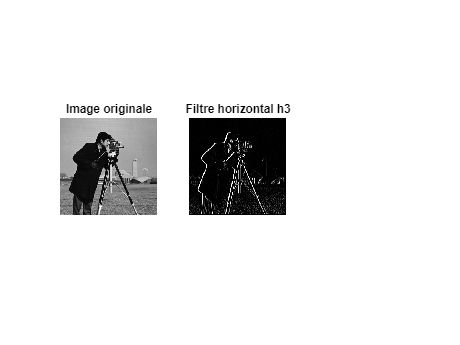

h3 = [1,0,-1;2,0,2;1,0,-1];

% Initialisation des images filtrées
I1f3 = zeros(m, n); % Pour le filtre horizontal

% Application du filtre (h3)
for i = 2:m-2
    for j = 2:n-2 
        I1f3(i, j,:) = h3(1,1) * im1(i-1, j-1) + h3(1,2) * im1(i-1,j) - im1(i-1, j+1) + h3(2,1) * im1(i,j-1) + h3(2,2) * im1(i,j) - h3(2,3) * im1(i,j+1) + h3(3,1) * im1(i+1,j-1) + h3(3,2) * im1(i+1,j) -  im1(i+1,j+1);
    end
end

% Affichage des résultats
figure;
subplot(1, 3, 1);
imshow(im1);
title('Image originale');

subplot(1, 3, 2);
imshow(I1f3,[]);
title('Filtre horizontal h3');

### h4

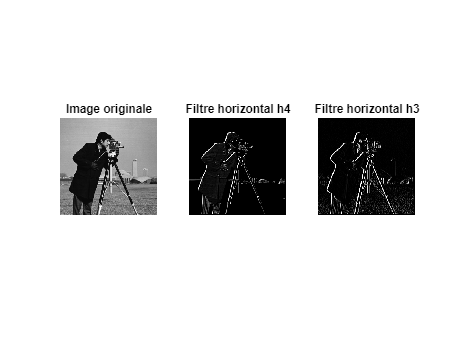

% Filtre h4
h4 = [2 1 0;1 0 -1;0 -1 -2];

% Initialisation des images filtrées
I1f4 = zeros(m, n); % Pour le filtre horizontal

% Application du filtre (h3)
for i = 2:m-2
    for j = 2:n-2 
        I1f4(i, j,:) = h4(1,1) * im1(i-1, j-1) + h4(1,2) * im1(i-1,j) + h4(1,3) * im1(i-1, j+1) + h4(2,1) * im1(i,j-1) + h4(2,2) * im1(i,j) - im1(i,j+1) + h4(3,1) * im1(i+1,j-1) - im1(i+1,j) - im1(i+1,j+1);
    end
end

% Affichage des résultats
figure;
subplot(1, 3, 1);
imshow(im1);
title('Image originale');

subplot(1, 3, 2);
imshow(I1f4,[]);
title('Filtre horizontal h4');

subplot(1, 3, 3);
imshow(I1f3,[]);
title('Filtre horizontal h3');

### h5

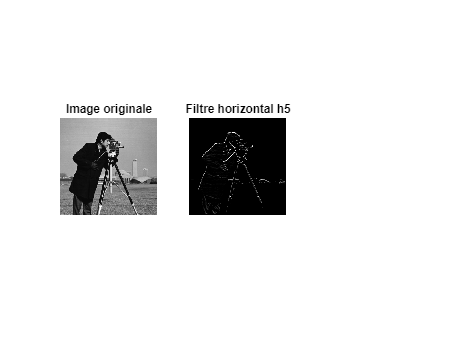

h5 = [1,2,1;0,0,0;-1,-2,-1];

% Initialisation des images filtrées
I1f5 = zeros(m, n); % Pour le filtre horizontal

% Application du filtre (h3)
for i = 2:m-2
    for j = 2:n-2 
        I1f5(i, j,:) = h5(1,1) * im1(i-1, j-1) + h5(1,2) * im1(i-1,j) + im1(i-1, j+1) + h5(2,1) * im1(i,j-1) + h5(2,2) * im1(i,j) + h5(2,3) * im1(i,j+1) - im1(i+1,j-1) - 2 * im1(i+1,j) -  im1(i+1,j+1);
    end
end

% Affichage des résultats
figure;
subplot(1, 3, 1);
imshow(im1);
title('Image originale');

subplot(1, 3, 2);
imshow(I1f5,[]);
title('Filtre horizontal h5');

### h6

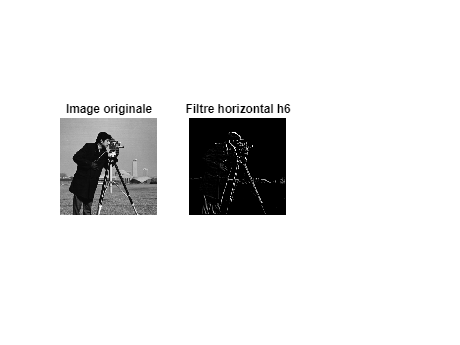

h6 = [0,1,2;-1,0,1;-2,-1,0];

% Initialisation des images filtrées
I1f6 = zeros(m, n); % Pour le filtre horizontal

% Application du filtre (h3)
for i = 2:m-2
    for j = 2:n-2 
        I1f6(i, j,:) = h6(1,1) * im1(i-1, j-1) + h6(1,2) * im1(i-1,j) + h6(1,3) * im1(i-1, j+1) - im1(i,j-1) + h6(2,2) * im1(i,j) + h6(2,3) * im1(i,j+1) - 2 * im1(i+1,j-1) - im1(i+1,j);
    end
end

% Affichage des résultats
figure;
subplot(1, 3, 1);
imshow(im1);
title('Image originale');

subplot(1, 3, 2);
imshow(I1f6,[]);
title('Filtre horizontal h6');

### Filtre moyenneur

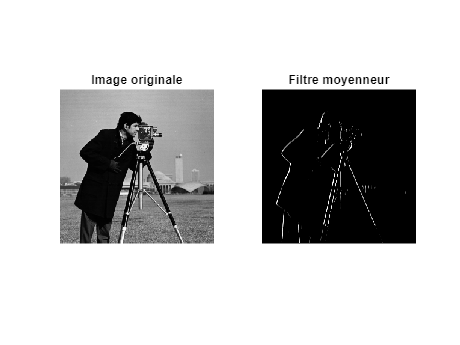

% Initialisation de l'image filtrée
imM = zeros(m, n);

% Application du filtre moyenneur (fenêtre 3x3)
for i = 2:m-1
    for j = 2:n-1
        imM(i, j) = ( ...
            im1(i-1, j-1) - im1(i-1, j) - im1(i-1, j+1) + ... % Ligne du haut
            im1(i, j-1) - im1(i, j) - im1(i, j+1) + ...       % Ligne du milieu
            im1(i+1, j-1) - im1(i+1, j) - im1(i+1, j+1) ...  % Ligne du bas
        ) / 9; % Moyenne des 9 pixels
    end
end

% Affichage des résultats
figure;
subplot(1, 2, 1);
imshow(im1, []);
title('Image originale');

subplot(1, 2, 2);
imshow(uint8(imM), []); % Conversion en uint8 pour affichage
title('Filtre moyenneur');